## TALLER — APRENDIZAJE PROFUNDO: DÍGITOS MANUSCRITOS (RESUELTO, PASO A PASO)

Asignatura : Inteligencia Computacional Aplicada

Docente    : Cesar Andrey Perdomo Charry

clear; clc; close all;
rng(42);                                   % reproducibilidad


%% PASO 1. DATOS: DigitsData (10 000 imágenes sintéticas de dígitos, 28x28, escala de grises)
%  OJO: son dígitos SINTÉTICOS generados por MathWorks, no son MNIST real.
%  Opciones para obtener la carpeta de imágenes (una subcarpeta por dígito):
%   a) Abra en MATLAB el ejemplo «Create Simple Image Classification Network
%      Using Deep Network Designer» (botón «Open Live Script»): trae DigitsData.zip.
%   b) Use las imágenes que exporta el cuaderno de Colab (carpeta con un .zip).
carpetaDatos = "DigitsData";
if ~isfolder(carpetaDatos) && isfile("DigitsData.zip")
    unzip("DigitsData.zip");
end
rutaAntigua = fullfile(matlabroot,"toolbox","nnet","nndemos","nndatasets","DigitDataset");
if ~isfolder(carpetaDatos) && isfolder(rutaAntigua)   % ubicación usada en versiones anteriores (verifique)
    carpetaDatos = rutaAntigua;
end
assert(isfolder(carpetaDatos), "No se encontró la carpeta de imágenes. Vea las opciones a) y b) arriba.");

imds = imageDatastore(carpetaDatos, IncludeSubfolders=true, LabelSource="foldernames");
clases = categories(imds.Labels);
numClases = numel(clases);
disp(countEachLabel(imds))

    Label    Count
    _____    _____

      0      1000 
      1      1000 
      2      1000 
      3      1000 
      4      1000 
      5      1000 
      6      1000 
      7      1000 
      8      1000 
      9      1000 



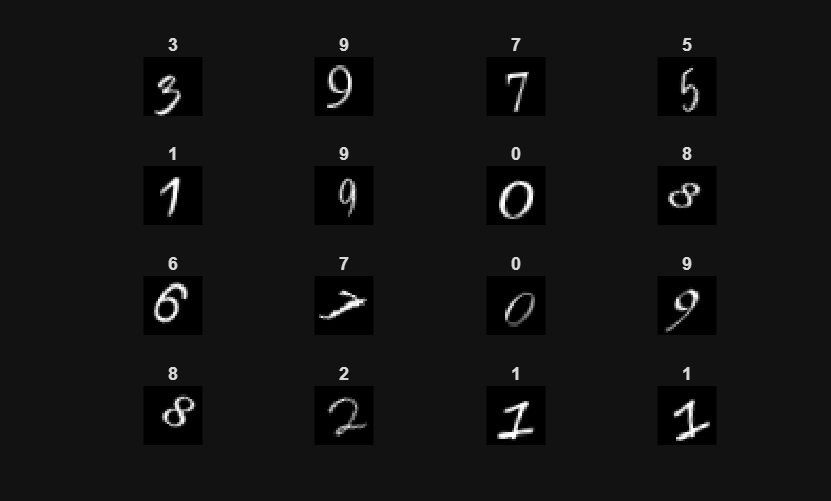


figure("Name","Muestras");
perm = randperm(numel(imds.Files), 16);
for k = 1:16
    subplot(4,4,k); imshow(imread(imds.Files{perm(k)}));
    title(string(imds.Labels(perm(k))));
end


% Partición entrenamiento / validación / prueba (70 / 15 / 15)
[imdsTrain, imdsVal, imdsTest] = splitEachLabel(imds, 0.7, 0.15, 0.15, "randomized");
fprintf("Entrenamiento: %d | Validación: %d | Prueba: %d\n", numel(imdsTrain.Files), numel(imdsVal.Files), numel(imdsTest.Files));

Entrenamiento: 7000 | Validación: 1500 | Prueba: 1500



%% PUNTO DE CONTROL 1
verificar("10 clases", numClases == 10, "debe haber una subcarpeta por dígito");

[OK]      10 clases


verificar("Imágenes de 28x28", isequal(size(readimage(imdsTrain,1),[1 2]), [28 28]), "revise el tamaño de las imágenes");

[OK]      Imágenes de 28x28


PASO 2. RED CONVOLUCIONAL

%  28x28x1 -> conv3x3(16) -> ReLU -> pool2 -> conv3x3(32) -> ReLU -> pool2 -> dropout -> FC(10) -> softmax
%  Tamaños: 28 -> 26 -> 13 -> 11 -> 5. Parámetros: 160 + 4 640 + 8 010 = 12 810.
layers = [
    imageInputLayer([28 28 1], Normalization="zscore")
    convolution2dLayer(3, 16)
    reluLayer
    maxPooling2dLayer(2, Stride=2)
    convolution2dLayer(3, 32)
    reluLayer
    maxPooling2dLayer(2, Stride=2)
    dropoutLayer(0.25)
    fullyConnectedLayer(numClases)
    softmaxLayer];

analyzeNetwork(layers)   % ventana con tamaños de activación y número de parámetros: compárelos con 12 810


PASO 3. ENTRENAMIENTO

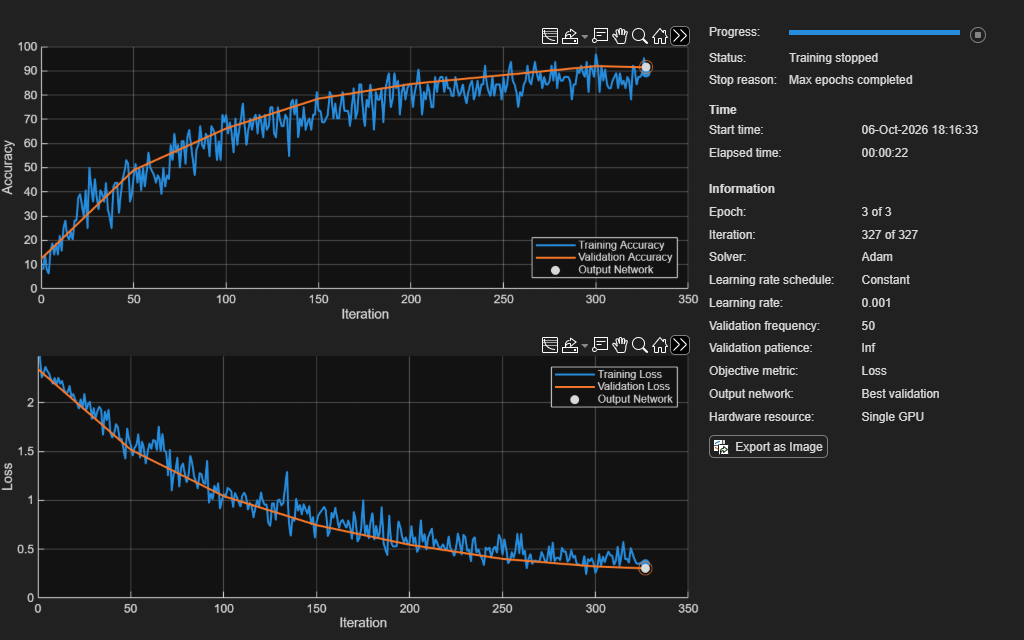

opciones = trainingOptions("adam", ...
    InitialLearnRate=1e-3, ...
    MaxEpochs=3, ...
    MiniBatchSize=64, ...
    Shuffle="every-epoch", ...
    ValidationData=imdsVal, ...
    ValidationFrequency=50, ...
    Metrics="accuracy", ...
    Plots="training-progress", ...
    Verbose=false);

net = trainnet(imdsTrain, layers, "crossentropy", opciones);

PASO 4. EVALUACIÓN EN PRUEBA

puntajes = minibatchpredict(net, imdsTest);          % N x numClases (probabilidades)
[~, idx] = max(puntajes, [], 2);
YPred = categorical(clases(idx), clases);
YTest = imdsTest.Labels;
exactitud = mean(YPred == YTest);
fprintf("Exactitud en prueba: %.4f (%d errores de %d)\n", exactitud, sum(YPred ~= YTest), numel(YTest));

Exactitud en prueba: 0.9180 (123 errores de 1500)


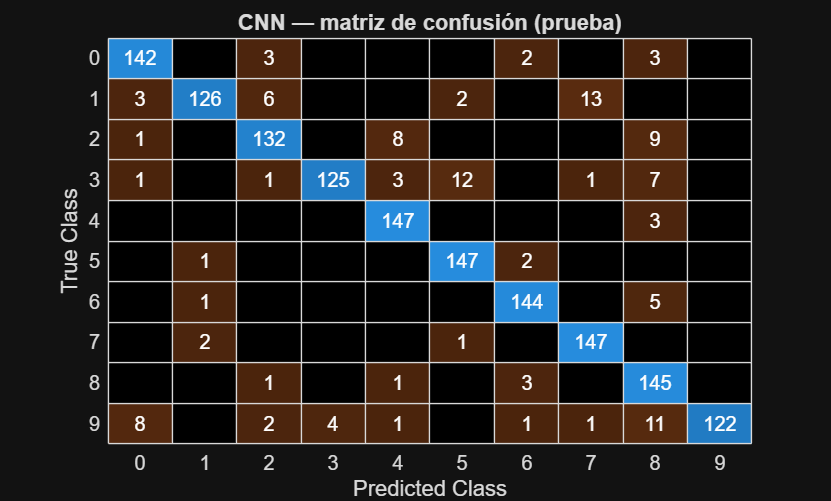


figure("Name","Matriz de confusión");
confusionchart(YTest, YPred);
title("CNN — matriz de confusión (prueba)");


cm = confusionmat(YTest, YPred);
fuera = cm - diag(diag(cm));                         % errores fuera de la diagonal
[mx, k] = max(fuera(:));
[fi, co] = ind2sub(size(fuera), k);
fprintf("Par más confundido: real %s -> predicha %s (%d veces)\n", clases{fi}, clases{co}, mx);

Par más confundido: real 1 -> predicha 7 (13 veces)



%% PUNTO DE CONTROL 2
verificar("La matriz de confusión suma el tamaño del conjunto de prueba", sum(cm(:)) == numel(YTest), "");

[OK]      La matriz de confusión suma el tamaño del conjunto de prueba


verificar("Exactitud en prueba > 90 %", exactitud > 0.90, "revise datos, épocas y la red");

[OK]      Exactitud en prueba > 90 %


PASO 5. MINI-EXPERIMENTO: TASA DE APRENDIZAJE (2 épocas cada una)

%  Antes de ejecutar, escriba su predicción: ¿cuál será la mejor y por qué?
tasas = [1e-1 1e-3 1e-5];
resultados = zeros(numel(tasas), 1);
for t = 1:numel(tasas)
    rng(42);
    op = trainingOptions("adam", InitialLearnRate=tasas(t), MaxEpochs=2, MiniBatchSize=64, ...
        Shuffle="every-epoch", Plots="none", Verbose=false);
    netT = trainnet(imdsTrain, layers, "crossentropy", op);
    pT = minibatchpredict(netT, imdsVal);
    [~, iT] = max(pT, [], 2);
    resultados(t) = mean(categorical(clases(iT), clases) == imdsVal.Labels);
    fprintf("lr = %-8g  exactitud de validación = %.4f\n", tasas(t), resultados(t));
end

lr = 0.1       exactitud de validación = 0.1000
lr = 0.001     exactitud de validación = 0.8653
lr = 1e-05     exactitud de validación = 0.1487


**PASO 6. DEEP NETWORK DESIGNER (diseño visual de la misma red)**

1) Escriba en la ventana de comandos:  deepNetworkDesigner

2) Elija «Blank Network» y arrastre desde la biblioteca las capas del Paso 2, en orden.

3) Seleccione cada capa y fije sus propiedades (filtros, tamaño, probabilidad de dropout).

4) Pulse «Analyze» para verificar tamaños; no debe haber errores.

5) Exporte la red (al espacio de trabajo o como código) y entrénela con trainnet, como en el Paso 3.

***Nota:**** la página de MathWorks sobre importación de datos en la app indica que no se recomienda importar datos y entrenar dentro de la app; use la app para diseñar y el código para entrenar.*

PASO 7. GUARDAR

save("cnn_digitos.mat", "net", "clases");


%% =========================================================================
%  FUNCIONES LOCALES
% =========================================================================
function verificar(nombre, ok, pista)
    if ok
        fprintf("[OK]      %s\n", nombre);
    else
        fprintf("[REVISAR] %s  ->  %s\n", nombre, pista);
    end
end